# All-Files Analysis

## Import All Data

clear;

datasets = dir('data/*.mat');
numfiles = length(datasets);
% numfiles = 1;
mydata = cell(1, numfiles);

% Import Data
for k = 1:numfiles
  mydata{k} = importdata(strcat('data/',datasets(k).name));
  mydata{k}.Source = datasets(k).name;
end

% Run simple analysis on all
% for k = 1:length(mydata)
%     sample = mydata(k);
%     Acceleration = sample{1}.Acceleration;
%     figure()
%     stackedplot(Acceleration);
%     title({'Time table visualization of printhead acceleration';strcat('\fontsize{8}\itFile:  ',sample{1}.Source)})
% end

## Plot All Data

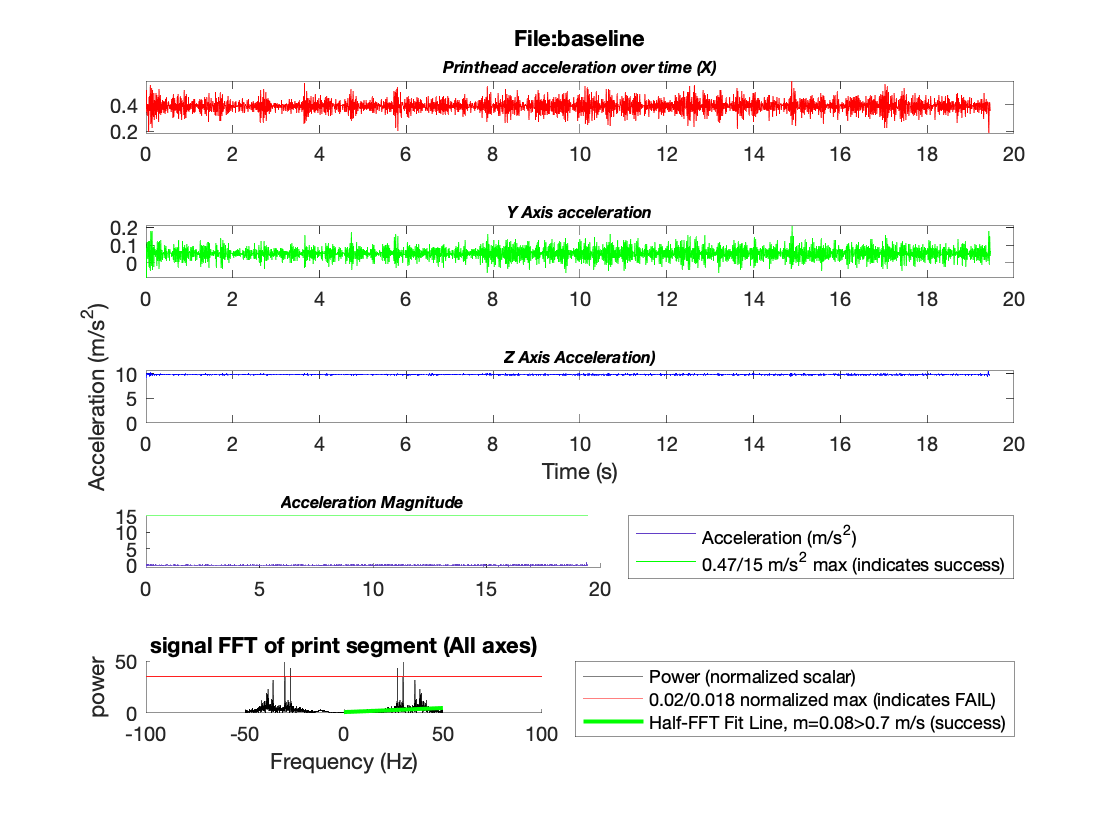

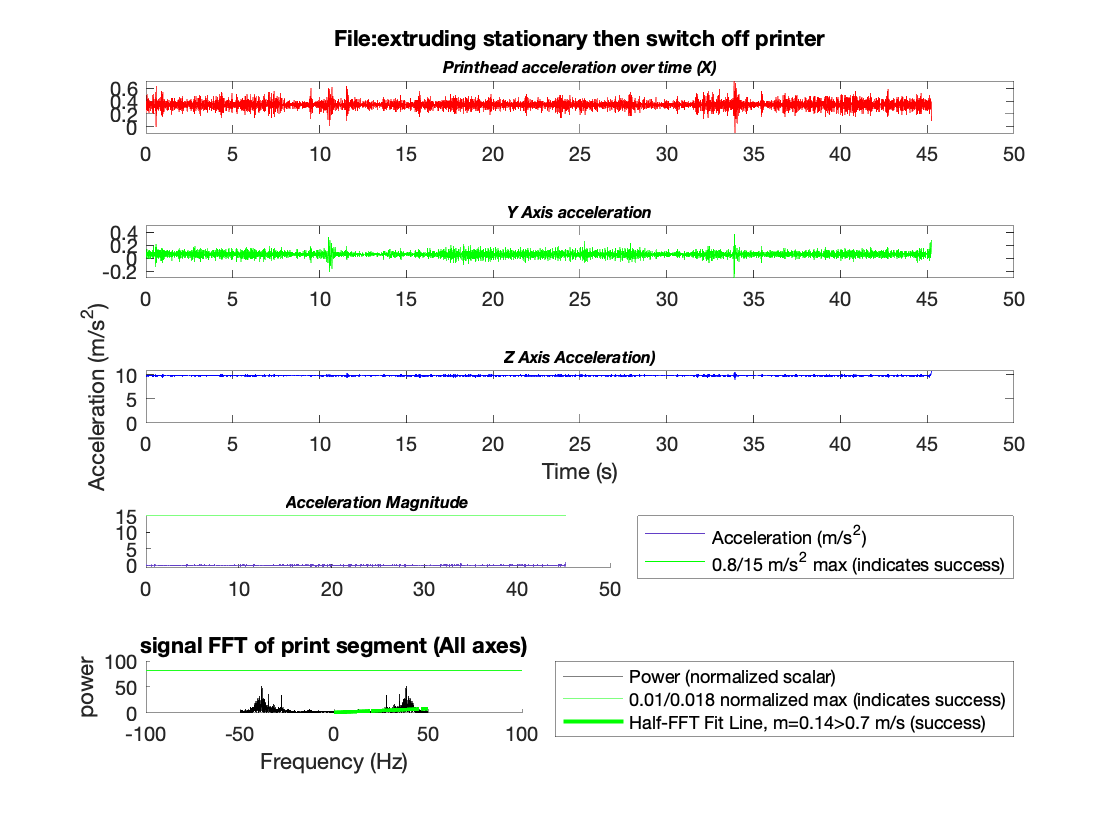

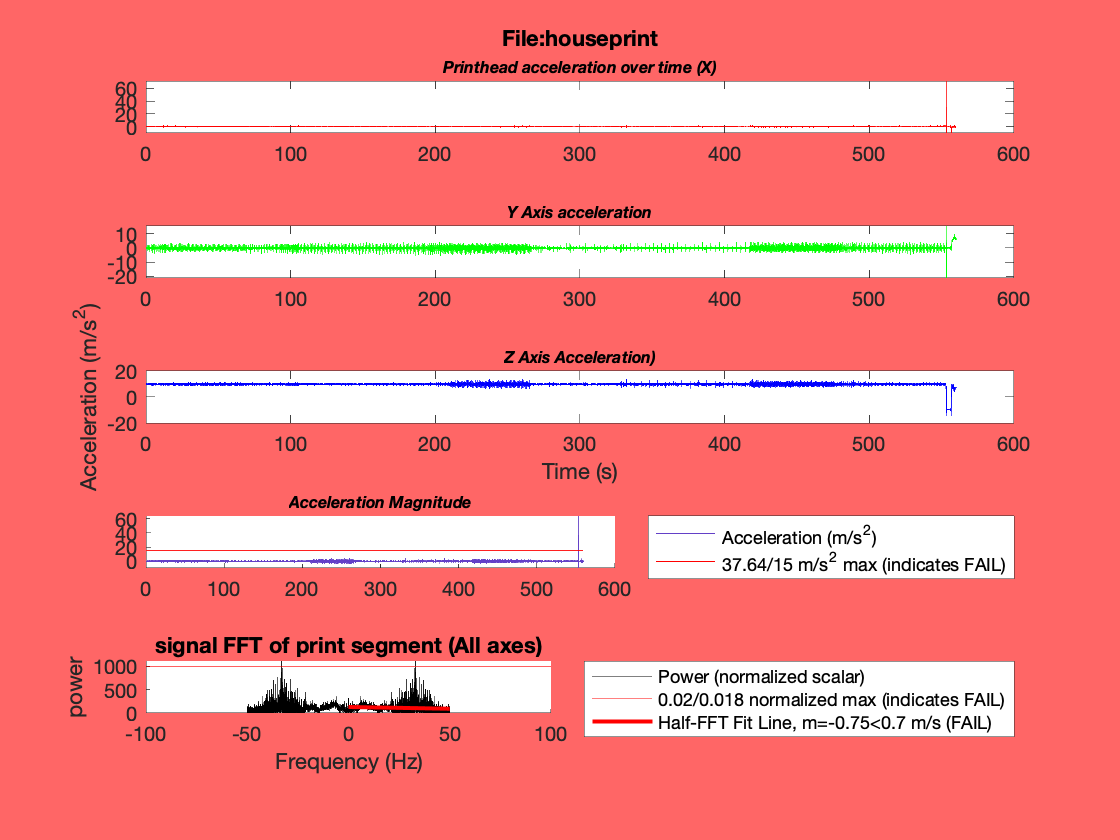

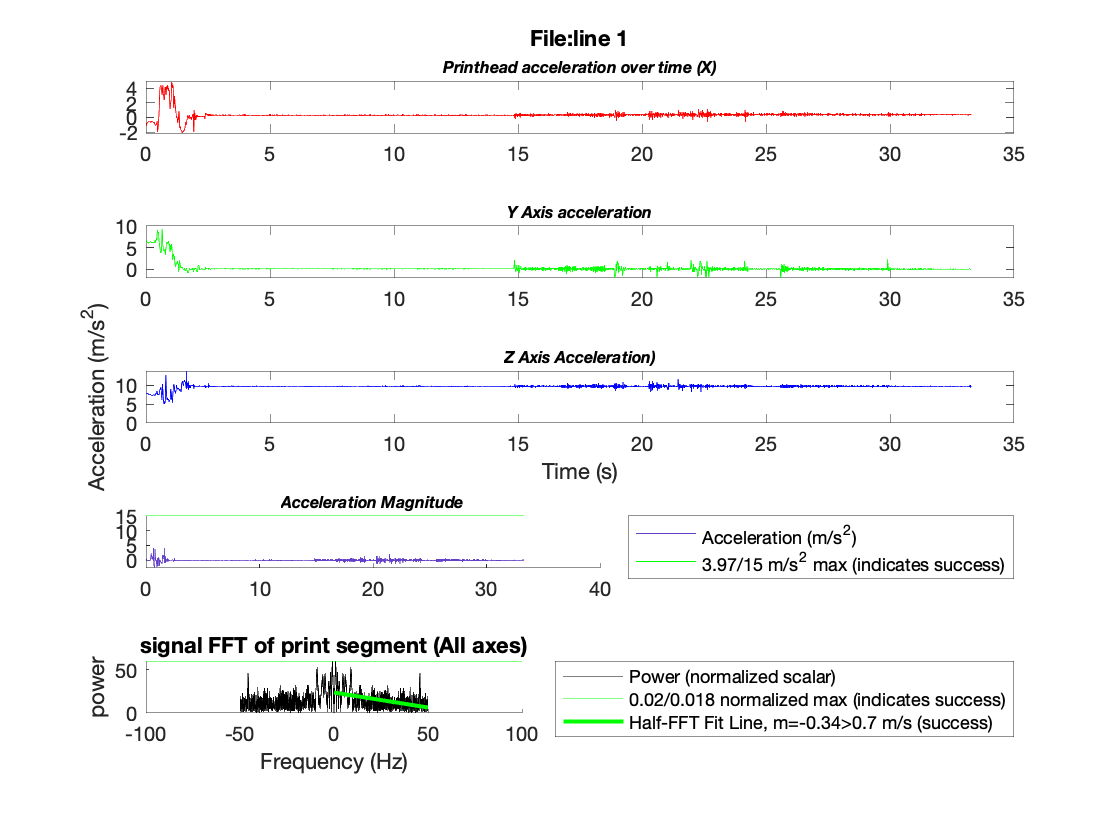

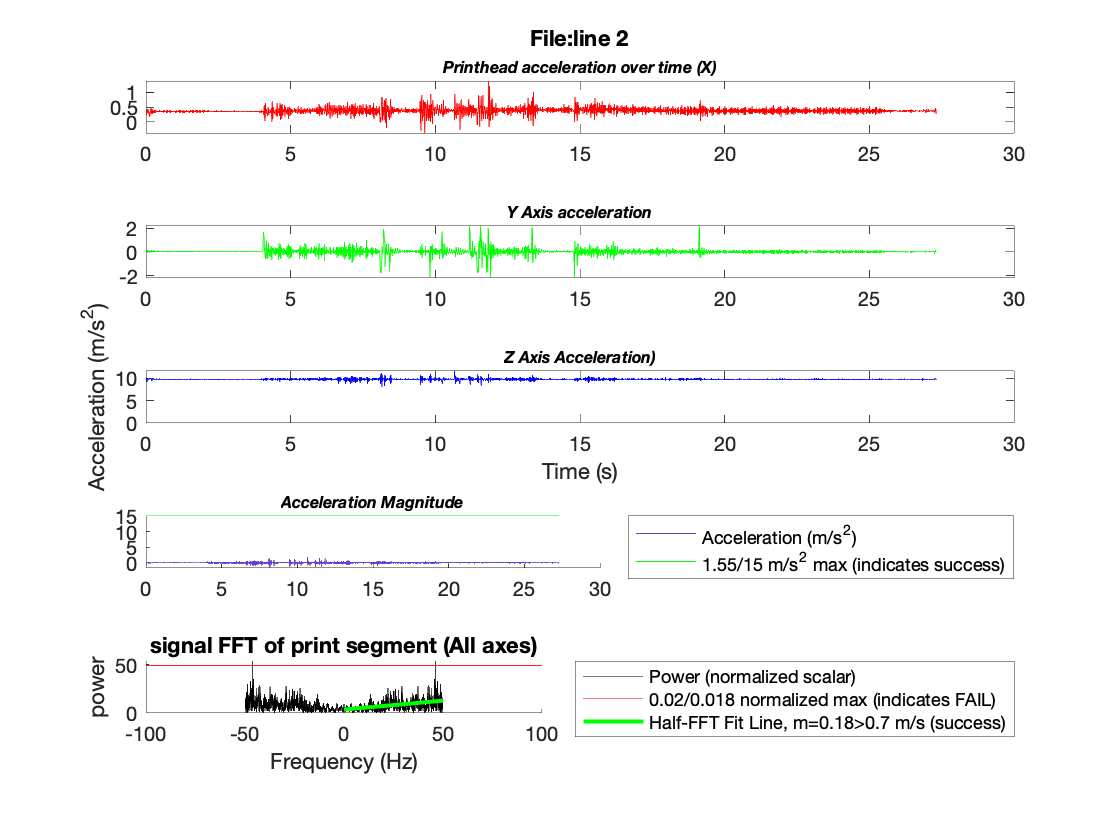

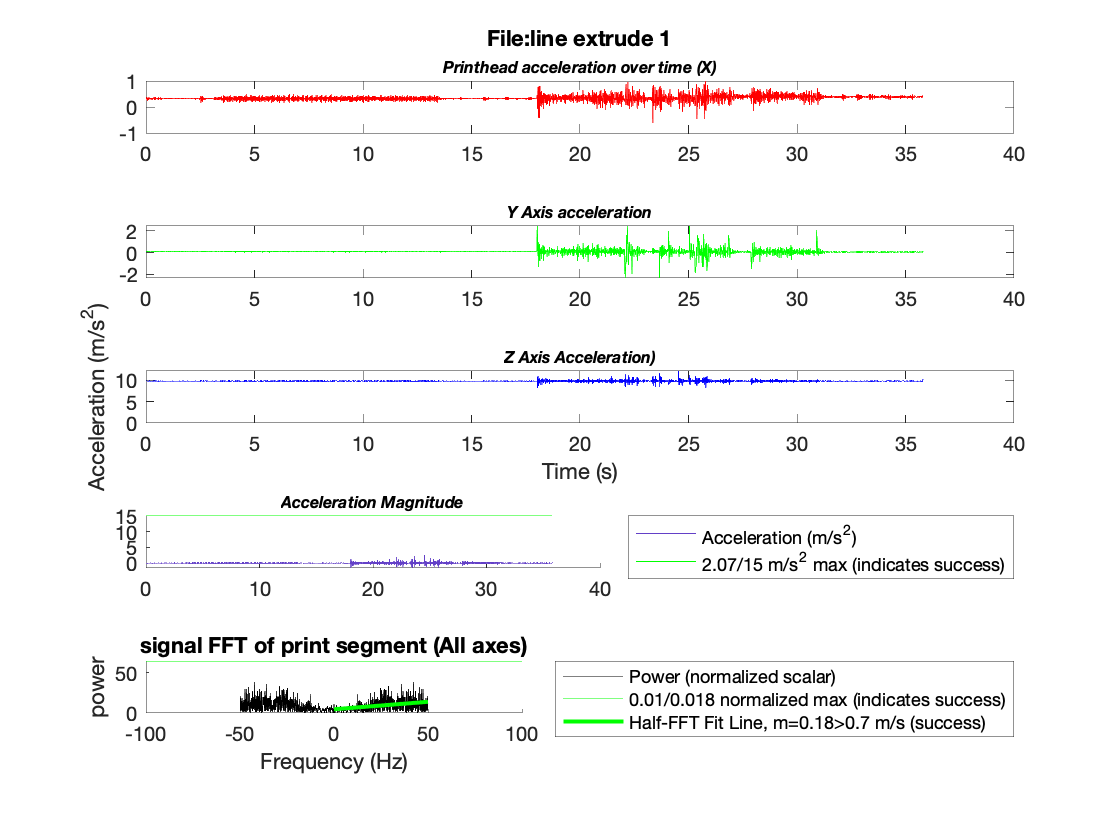

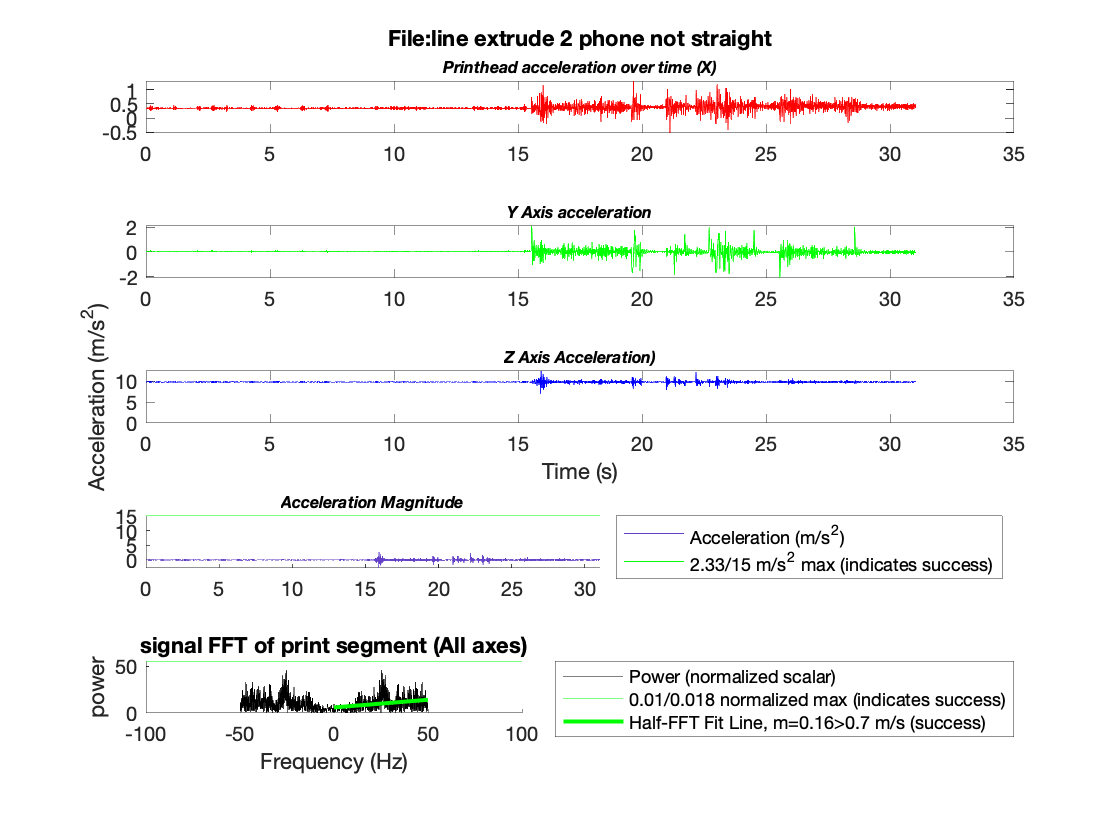

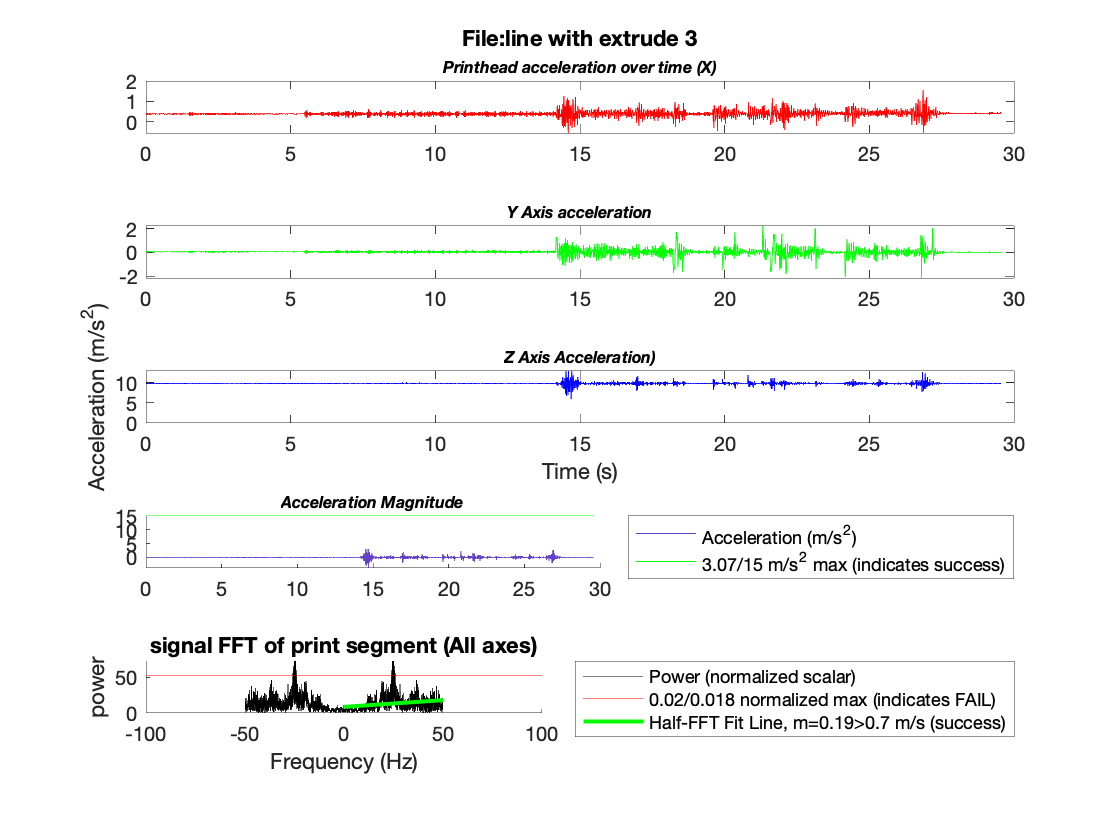

tic
for k = 1:length(mydata)
    sample = mydata(k);
    Acceleration = sample{1}.Acceleration;
    t = linspace(0,height(Acceleration)/100,height(Acceleration));
    figure()
    a = timetable2table(Acceleration);
    accelData = [a.X a.Y a.Z]';
    
    subplot(5,1,1);
    plot(t,accelData(1,:), 'r')
    title({strcat('File: ',sample{1}.Source(1:end-4));"\fontsize{8}\itPrinthead acceleration over time (X)"})
    
    subplot(5,1,2);
    plot(t,accelData(2,:), 'g')
    title("\fontsize{8}\itY Axis acceleration")
    
    subplot(5,1,3);
    plot(t,accelData(3,:), 'b')
    title("\fontsize{8}\itZ Axis Acceleration)")
    xlabel("Time (s)")
    ylabel("Acceleration (m/s^2)")
    hold on;
    plot([0,0],[0,0])
    
    subplot(5,1,4);
    accelData = [a.X a.Y a.Z]';
    x = vecnorm(accelData);
    x = x - mean(x);
    hold on;
    plot(t,x, 'Color', [99, 64, 199]./255)
    title("\fontsize{8}\itAcceleration Magnitude")
    
    [success, level] = classify_accel_threshold(x);
    if success
        plot([0 length(x)/100], [15 15], 'g')
        legend('Acceleration (m/s^2)', strcat(string(round(level,2)),'/15 m/s^2 max (indicates success)'), 'Location', 'bestoutside')
    else
        plot([0 length(x)/100], [15 15], 'r')
        legend('Acceleration (m/s^2)', strcat(string(round(level,2)),'/15 m/s^2 max (indicates FAIL)'), 'Location', 'bestoutside')
        set(gcf, 'color', [1 0.4 0.4])
    end
    hold off;
    
    subplot(5, 1, 5);
    N = length(x);
    Fs = 100; % sampling rate of 100Hz
    f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
    FA = fft(x);
    fftOutput = fftshift(abs(FA));
    hold on;
    plot(f,fftOutput,'Color',[0 0 0]./255);
    title("signal FFT of print segment (All axes)")
    xlabel("Frequency (Hz)")
    ylabel("power")
    sampleLength = length(fftOutput);
    normalizedSample = fftOutput./sampleLength;
    [success, level] = classify_fft_threshold(normalizedSample, 0.018);
    if success
        plot([-100 100], ones(2)*0.018*sampleLength, 'g')
        legend('Power (normalized scalar)', strcat(string(round(level,2)),'/0.018 normalized max (indicates success)'), 'Location', 'bestoutside')
    else
        plot([-100 100], ones(2)*0.018*sampleLength, 'r')
        legend('Power (normalized scalar)', strcat(string(round(level,2)),'/0.018 normalized max (indicates FAIL)'), 'Location', 'bestoutside')
        % set(gcf, 'color', [1 0.4 0.4])
    end
    
    d = round(length(fftOutput)/2);
    halfF = f(d:end);
    halfFFToutput = fftOutput(d:end);
    % plot(halfF,halfFFToutput);
    p = polyfit(halfF,halfFFToutput,1);
    
    if p(1) > -0.7
        plot(halfF,polyval(p,halfF),'g','LineWidth',2.0,'DisplayName',strcat('Half-FFT Fit Line, m=',string(round(p(1),2)),'>0.7 m/s (success)'))
    else
        plot(halfF,polyval(p,halfF),'r','LineWidth',2.0,'DisplayName',strcat('Half-FFT Fit Line, m=',string(round(p(1),2)),'<0.7 m/s (FAIL)'))
    end
    
    
    
    
    
    saveas(gcf, strcat('./imgs/',sample{1}.Source(1:end-4),'.png'))
end

toc

Elapsed time is 24.237951 seconds.


## Run Simple Success Analysis